# Interpolation versus regression

## Interpolation

x = [250 300 400 500];
y = [0.675 0.616 0.525 0.457];  % "Nøjagtige" data
p = polyfit(x,y,3) %giver coeficenterne fra polynomiet ud   %fitter et polynomie til data x og y  % Grad = 3 = antal datapunkter minus 1

p =      -2.6e-09     4.27e-06    -0.002937        1.183


xx = linspace(250,500);
yy = polyval(p,xx) % finder værdien i et eller flere punkter i et polynomie

yy =         0.675      0.67176      0.66855      0.66536      0.66221      0.65908      0.65599      0.65292      0.64987      0.64686      0.64387      0.64091      0.63798      0.63508       0.6322      0.62934      0.62651      0.62371      0.62094      0.61818      0.61546      0.61275      0.61008      0.60742      0.60479      0.60218       0.5996      0.59704       0.5945      0.59199       0.5895      0.58702      0.58458      0.58215      0.57974      0.57736      0.57499      0.57265      0.57033      0.56802      0.56574      0.56347      0.56123        0.559       0.5568      0.55461      0.55244      0.55029      0.54815      0.54604


help polyval

 polyval Evaluate polynomial.
    Y = polyval(P,X) returns the value of a polynomial P evaluated at X. P
    is a vector of length N+1 whose elements are the coefficients of the
    polynomial in descending powers:
 
        Y = P(1)*X^N + P(2)*X^(N-1) + ... + P(N)*X + P(N+1)
 
    The polynomial P is evaluated at all points in X. See POLYVALM for
    evaluation of a polynomial P in a matrix sense.
 
    [Y,DELTA] = polyval(P,X,S) uses the optional output structure S created
    by POLYFIT to generate prediction error estimates DELTA. DELTA is an
    estimate of the standard deviation of the error in predicting a future
    observation at X by P(X).
 
    If the coefficients in P are least squares estimates computed by
    POLYFIT, and the errors in the data input to POLYFIT are independent,
    normal, with constant variance, then Y +/- DELTA will contain at least
    50% of future observations at X.
 
    Y = polyval

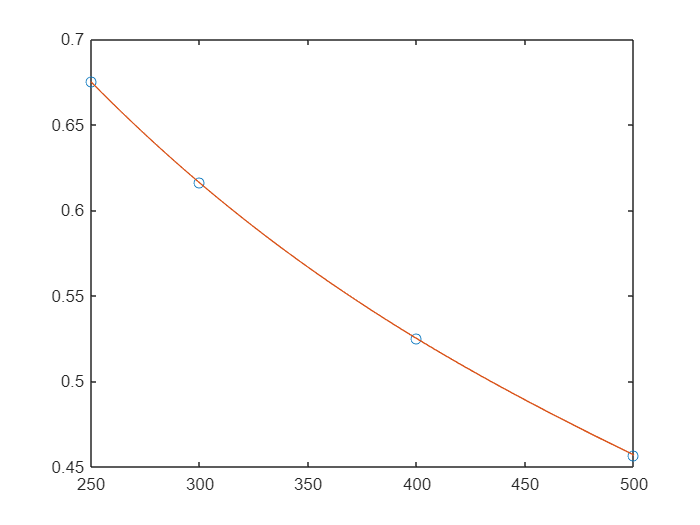

plot(x,y,'o',xx,yy)

## Regression (**ikke** i M3NUM1, men i M4STI1)

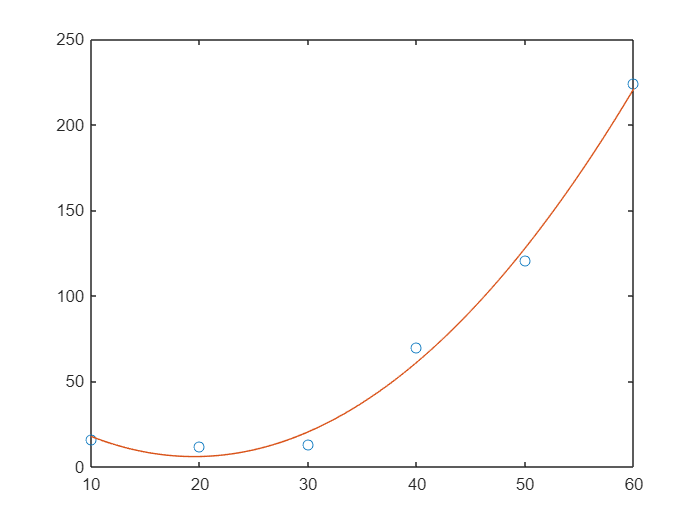

x = [10 20 30 40 50 60];
y = [15.8 12.0 12.9 69.9 120.6 223.8];  % Støjbehæftede data
p = polyfit(x,y,2);                     % Grad = fx 2 < antal datapunkter minus 1
xx = linspace(10,60);
yy = polyval(p,xx);
plot(x,y,'o',xx,yy)